N = 0;
% design vector x
% = [torque_Ls, torque_Rs, xs, ys, vs, thetas, thetadots, Tf]
x0 = [zeros(7*N,1); 1];

costfcn = @(x) x(end);

options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'Display', 'iter');

path = [0,0;5,0;5,5;10,5];
xstar = fmincon(costfcn, x0,[],[],[],[],[],[], @(x)nonlcon_path(x,path), options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     352    1.000000e+00    1.000e+01    5.000e-01


    1     704    9.819456e-01    9.689e+00    5.000e-01    2.655e+00
    2    1056    4.926836e-03    5.244e+00    4.366e-04    5.490e+00
    3    1408    1.703359e-02    4.822e+00    2.583e-03    5.374e+00
    4    1760    3.274769e-02    4.010e+00    1.696e-02    4.290e+00
    5    2112    6.524330e-02    4.049e+00    7.254e-03    3.720e+00
    6    2464    2.867301e-01    3.462e+00    3.280e-01    4.522e+00
    7    2816    8.622402e-01    3.439e+00    6.639e-02    5.954e+00
    8    3168    1.449742e+00    3.375e+00    4.113e-01    2.949e+00
    9    3520    2.024779e+00    3.043e+00    8.622e-01    1.896e+00
   10    3872    2.217828e+00    2.905e+00    1.029e+00    7.915e-01
   11    4224    2.300976e+00    2.747e+00    1.103e+00    5.194e-01
   12    4576    2.340575e+00    2.675e+00    1.139e+00    3.135e-01
   13    4928    2.355499e+00    2.583e+00    1.157e+00    3.041e-01
   14    5280    2.362974e+00    2.536e+00    1.165e+00    2.136e-01
   15    5632    2.363110e+00    2

xstar =     0.0328
   -0.0349
   -0.0159
    0.0186
    0.0056
   -0.0103
   -0.0005
    0.0009
    0.0010
    0.0006


% xstar = it_nonlcon(costfcn, x0, options);

% Extract states from design vectorgit 
[ts, tauL, tauR, x, y, v, th, th_dot] = unpack_design_vector(xstar);
disp(x);

         0
    0.0000
   -0.4236
   -0.2457
   -0.2227
   -0.2422
   -0.4294
   -0.3108
   -0.3027
   -0.3034
   -0.3034
   -0.3025
   -0.2978
   -0.2835
   -0.2491
   -0.1852
   -0.0988
    0.0132
    0.1551
    0.3254
    0.5054
    0.6784
    0.8414
    0.9984
    1.1503
    1.2921
    1.4141
    1.5098
    1.5800
    1.6317
    1.6738
    1.7124
    1.7492
    1.7819
    1.8096
    1.8314
    1.8485
    1.7559
    1.3587
    1.4221
    2.4621
    4.5501
    4.5409
    4.5548
    4.5532
    4.5031
    4.5258
    5.4999
    7.4347
   10.0000



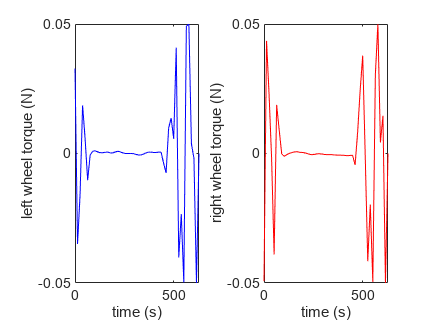


% Plot all states and trajectory
figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

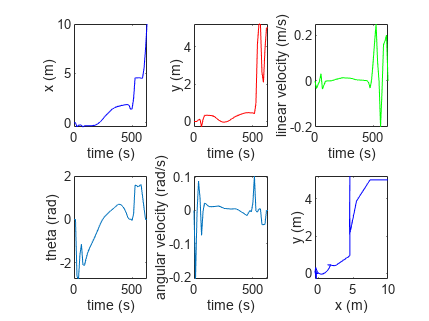


figure
hold on
subplot(2, 3, 1);
plot(ts, x, 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, y, 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, v, 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, th)
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, th_dot)
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(x, y, 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

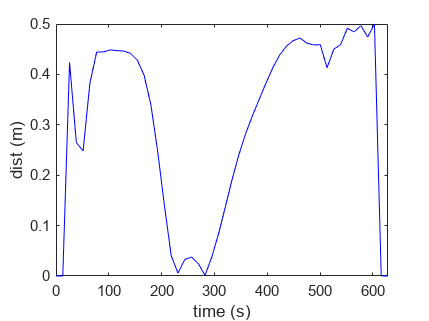

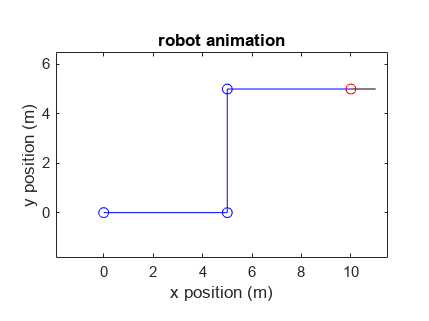


figure
dists = zeros(N,1);
for i = 1:N
    dists(i) = minDistance([x(i),y(i)], path);
end
plot(ts, dists, 'b-')
xlabel("time (s)")
ylabel("dist (m)")

animate_direct_collocation(xstar, path)